# **IO3xx SPI - Loopback Master Sync Multislave**

This example demonstrates the SPI code module functionalities using several **SPI** blocks***,*** which are both on the same I/O module connected to a loopback. One of the SPI blocks is set to master mode with multislave control and the other blocks are set to slave mode. You can test the basic functionality of the SPI code module by running this loopback test. 

## Setup

### Prerequisites

You will require the following to run this example:

- A Speedgoat real-time target machine with one I/O module from the IO3xx family installed

- A Speedgoat configuration file that supports at least **2 x SPI channels**

- A connector cable from the I/O module to the terminal board

- A terminal board with jumper wires

### Test Setup

In this example, data is sent from the SPI master to several SPI slaves and vice versa. You must therefore connect the pins on the terminal board where these channels are located. The exact pins depend on the configuration file (bitstream) used. 

In the pin mapping of your configuration file, look for the functionalities specified in the table below and then locate the corresponding pins on the terminal board. Connect these pins with jumper wires. 

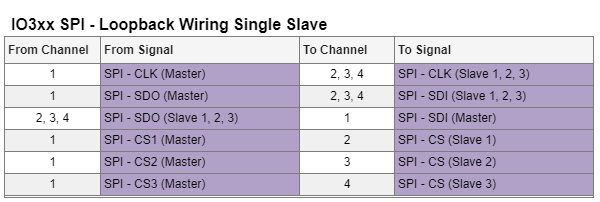

## Initialize and Open the Simulink Model

% Open Simulink model
modelName = 'sgMdl_IO3xx_SPI_Loopback_MasterSyncMultiSlave';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

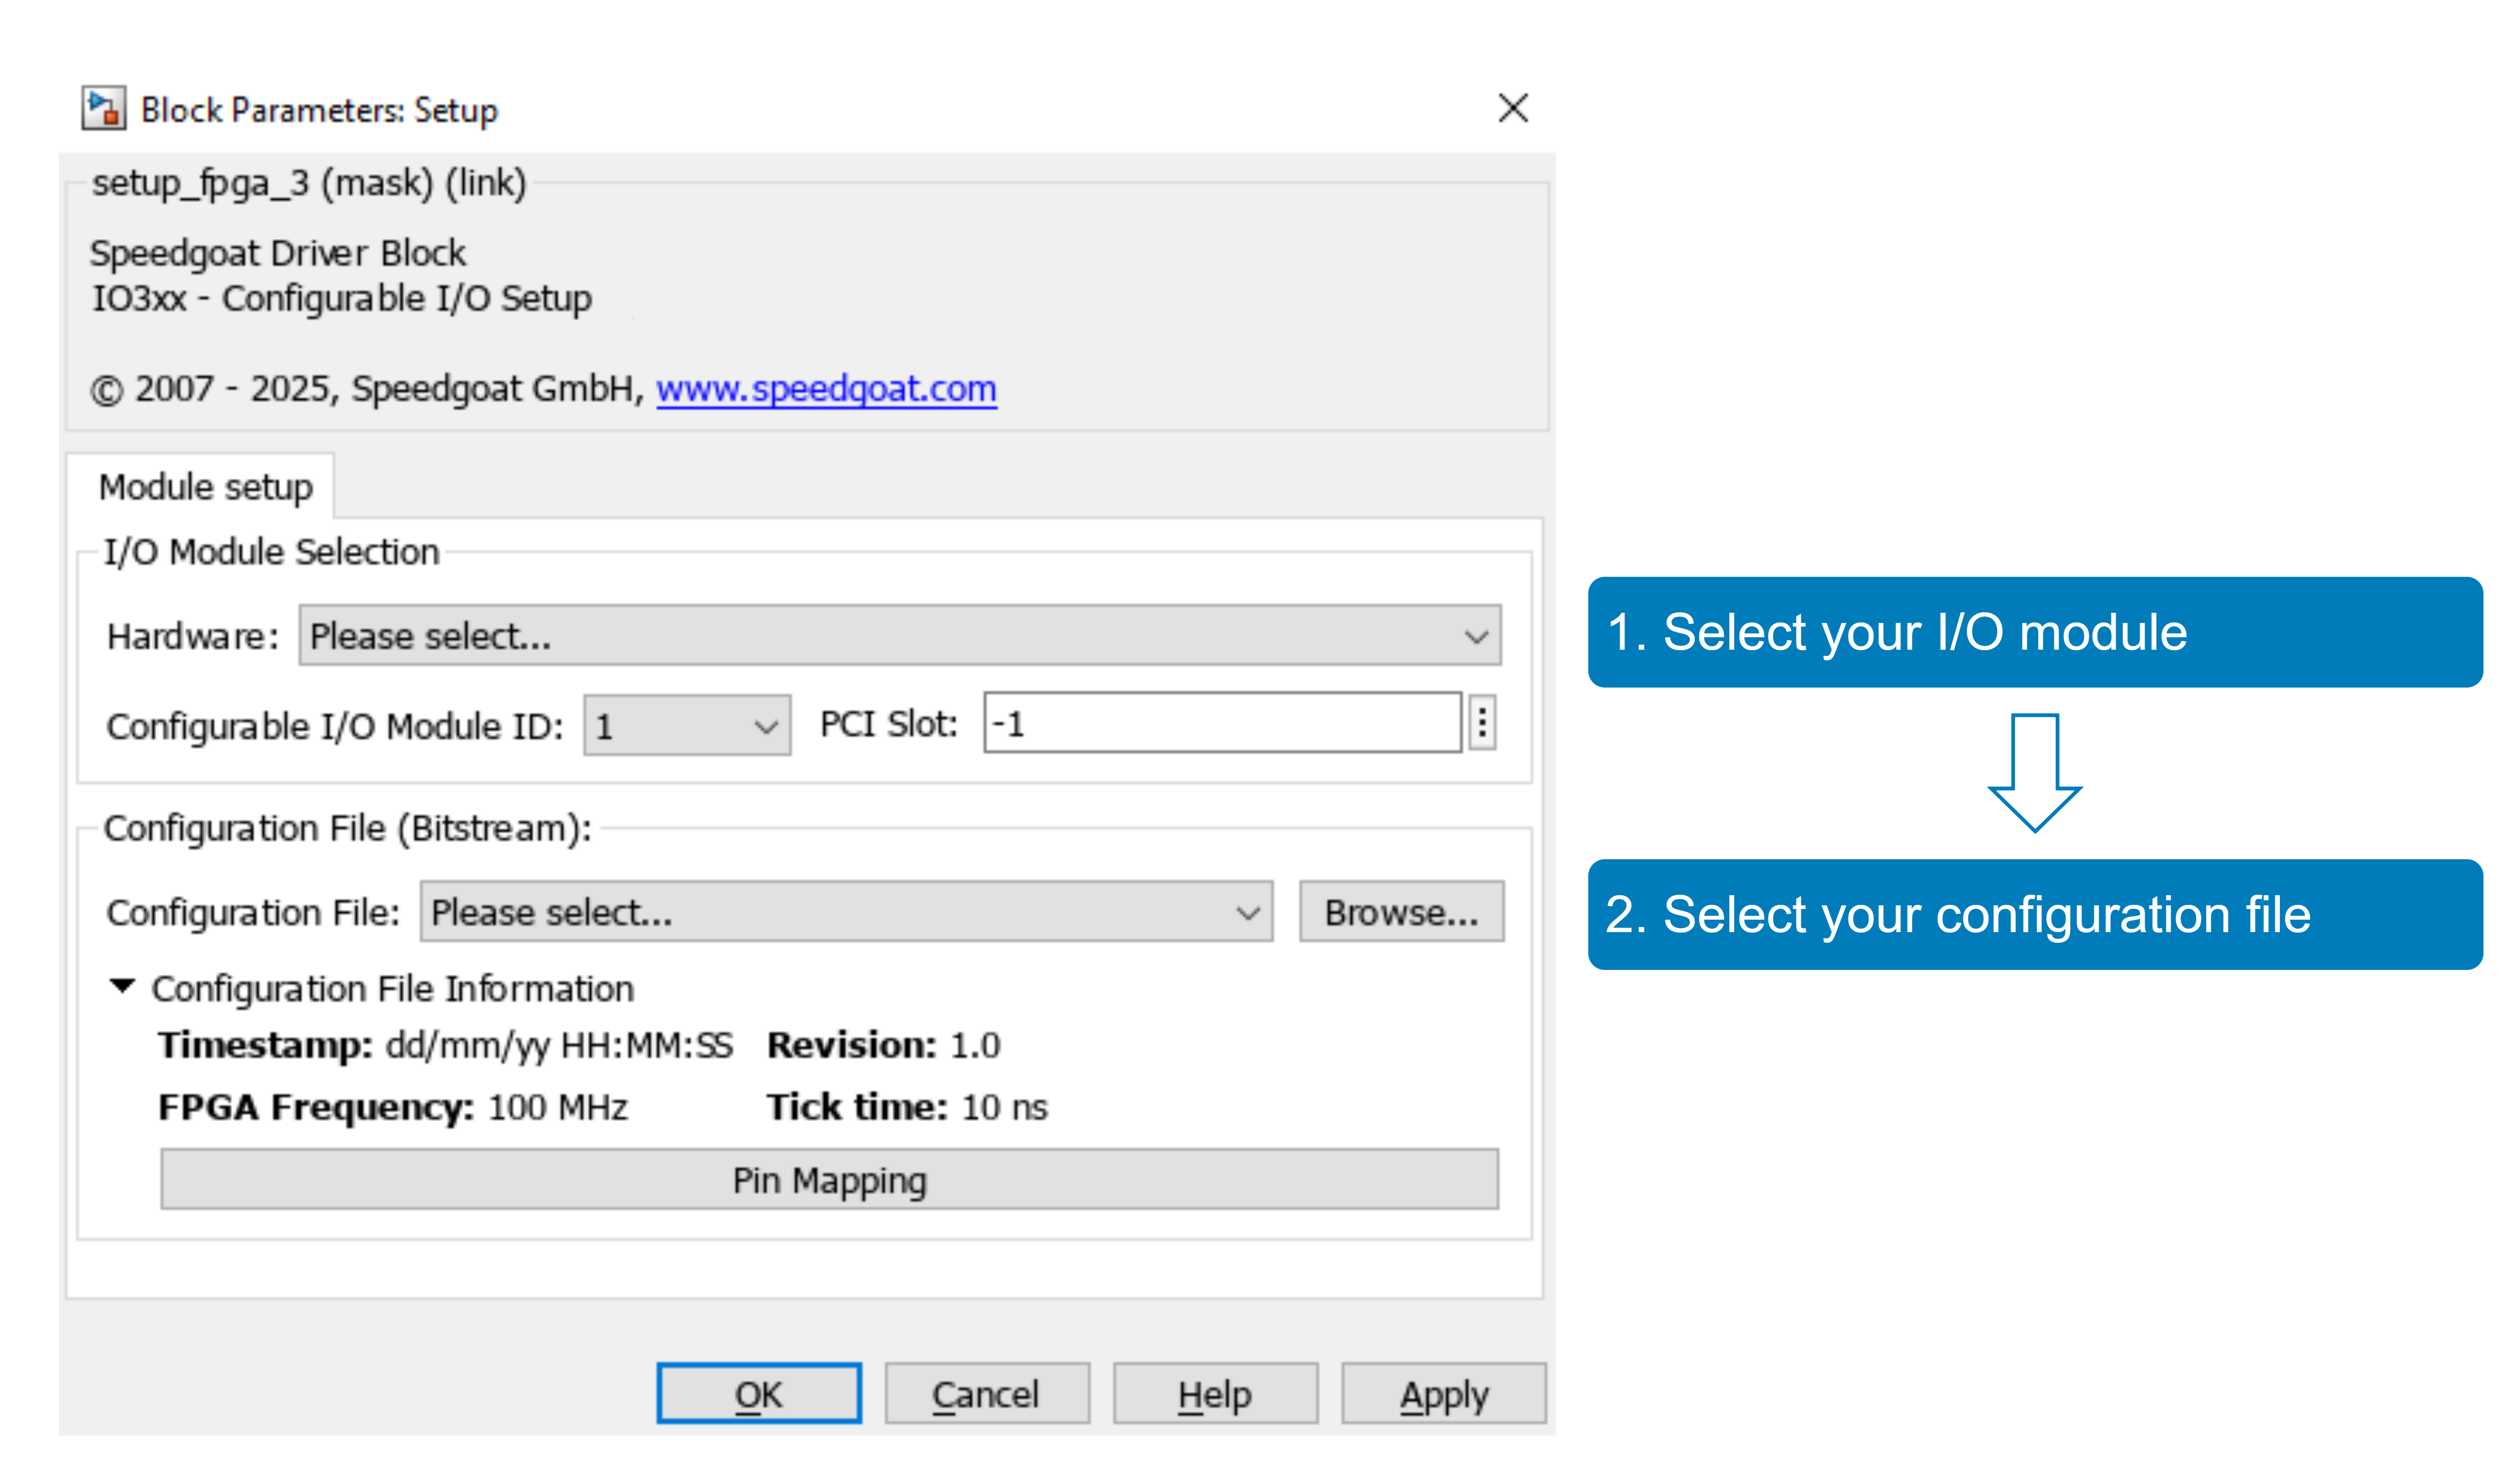

With the **Pin Mapping** button you can now check where the functionalities are located.

## Model Description

### SPI Master

In the model on the block **SPI Master**, the parameter **Role** is set to master and the parameter** Multislave Channel Vector** is set to **[1 2 3]**. That means that this SPI unit defines the details of the SPI data transfer and communicates with three slaves:

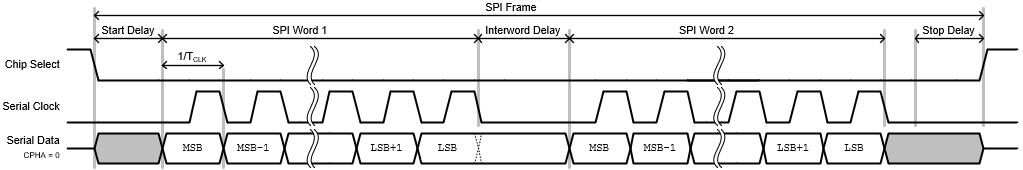

The following parameters are available in master mode to define the SPI frame:

- **CPOL** and **CPHA** define clock phase and clock polarity (both set 0 in this example)

- **Transmission Frequency** can be used to set the desired baud rate. Note that not all baud rates can be exactly met since the time resolution is limited to the FPGA Frequency of the used IO3xx Module. Next to this parameter the **Effective Frequency** informs about the real value that is applied (as close as possible to the desired value)

- **Start Delay** defines the delay at the SPI frame start (Chip select activation until frame start)

- **Interword Delay** defines the delay within the different words being transferred

- **Stop Delay** defines the delay that is additionally added after the last word has been transferred until Chip Select is deactivated again

- **Delay Compensation** can be used to compensate a delay between SPI master clock and slave serial data, which occurs due to physical signal transfer delays

- **Words per Frame** defines the number of words being transferred within a single SPI transfer

- **Bits per Word** defines the number of bits being transferred within a single data word

- **Transmit LSbit first** defines if each word shall be transferred with the LSB first

*NOTE: In this example, the communication parameters are set differently for each slave*

### SPI Slave

In the model on the block **SPI Slaves**, 3 SPI channels (2–5) of the SPI code module are selected, the parameter **Role** is set to slave.

The following parameters are available in slave mode to define the SPI frame:

- **CPOL** and **CPHA** define clock phase and clock polarity

- **Words per Frame** defines the number of words being transferred within a single SPI transfer

- **Bits per Word** defines the number of bits being transferred within a single data word

- **Transmit LSbit first** defines if each word shall be transferred with the LSB first

### SPI Multislave Behavior

The master is communicating with 3 different slaves. The physical signals SCLK of the master and all slaves are connected together, same for MOSI (master SDO, slave SDIs) and MISO (slave SDOs, master SDI). There are different CS signals on the master where each is connected to one of the slaves:

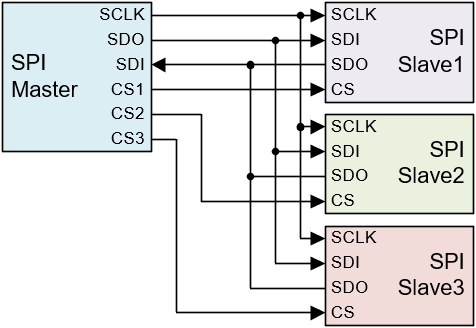

Each SPI transmission is then scheduled as follows. The master starts communication with the lowest numbered slave. When this is done, the master starts communication with the next slave, and so on:

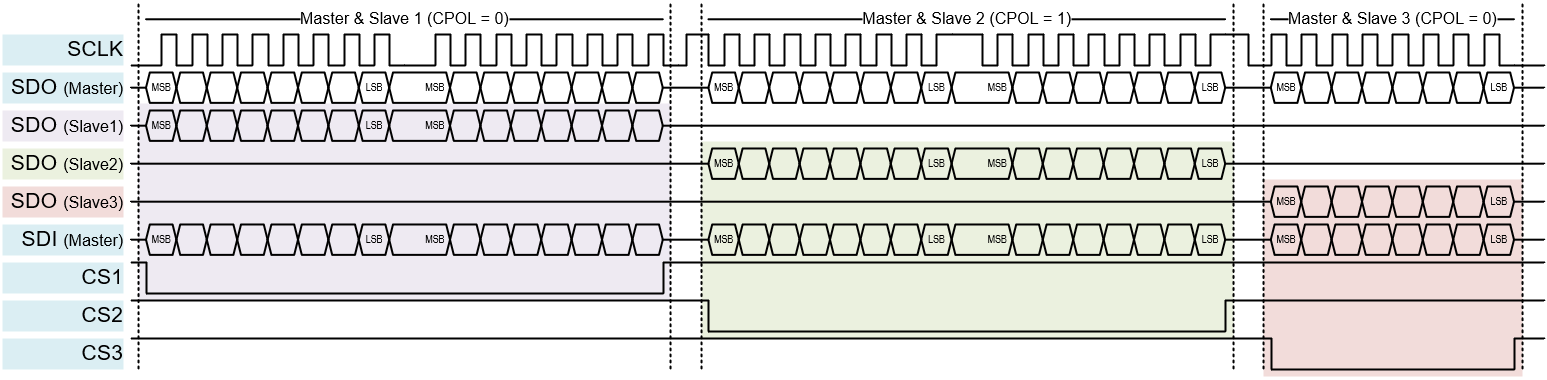

*Note that the communication parameters can be different between each SPI slave. In this picture, slave 2 got a different CPOL than the other two slaves and the master writes/reads more data to/from the first two slaves.*

### Model Behavior

The **SPI master** block defines the SPI frame. The **Words per Frame** is set to 12 and the **Bits per Word** is set to 8. With the **Transmission Frequency** set to 1 MHz for slave1, 750 kHz for slave2, 500 kHz for slave2, **Start Delay** set to 2 μs, **Interword Delay** set to 5 μs, and **Stop Delay** set to 2 μs, the total Frame length is 533 μs. This time is also displayed on the mask of the **SPI Master** block.

In the **SPI Master** block, the parameter **Sync Mode** is activated. This means that at each model sample step (which is 1 ms for this model), the SPI master initiates a new SPI frame transmission. In this case, the underlying driver of the **SPI master** block actively waits until the SPI frame is finished. Therefore it is crucial that the total length of the SPI frame is smaller than the model sample step time.

Note that the **Words per Frame** of the SPI master is set to 8, but the **Words per Frame** of the SPI slaves 2 and 3 are only set to 4 and 2. In this case, slaves 2 and 3 only receive the first 4 or 2 data words from the master and only send 4 or 2 Tx data words back to the master, the remaining data words are transmitted as 0.

#### Transferred Data from Master to Slave

The Tx data from the **SPI Master** block is based on a free-running counter (incremented with each model step or SPI frame). Different offsets are added to the counter values, so the data is different for every receiving slave.

#### Transferred Data from Slave to Master

The Tx data from the **SPI Slave** block is based on a free-running counter (incremented with each model step or SPI frame). Different offsets are added to the counter values, so the data is different for each transmitting slave.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model:

% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 
tg.setStopTime(10);
% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode','external')    % put model into External Mode
set_param(modelName,'SimulationCommand','connect')  % connect with External Mode  
% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

## Check the Results

### Received Data at Master

To check if the loopback is working as expected, open the Simulink scope **Data Rx Master** that is connected to the following signals:

- RxDataMaster_Slave1: The received data on the SPI master from Slave1 are displayed here. They should be equal to the SPI slave1 Tx data

- RxDataMaster_Slave2: The received data on the SPI master from Slave2 are displayed here. They should be equal to the SPI slave2 Tx data

- RxDataMaster_Slave3: The received data on the SPI master from Slave3 are displayed here. They should be equal to the SPI slave3 Tx data

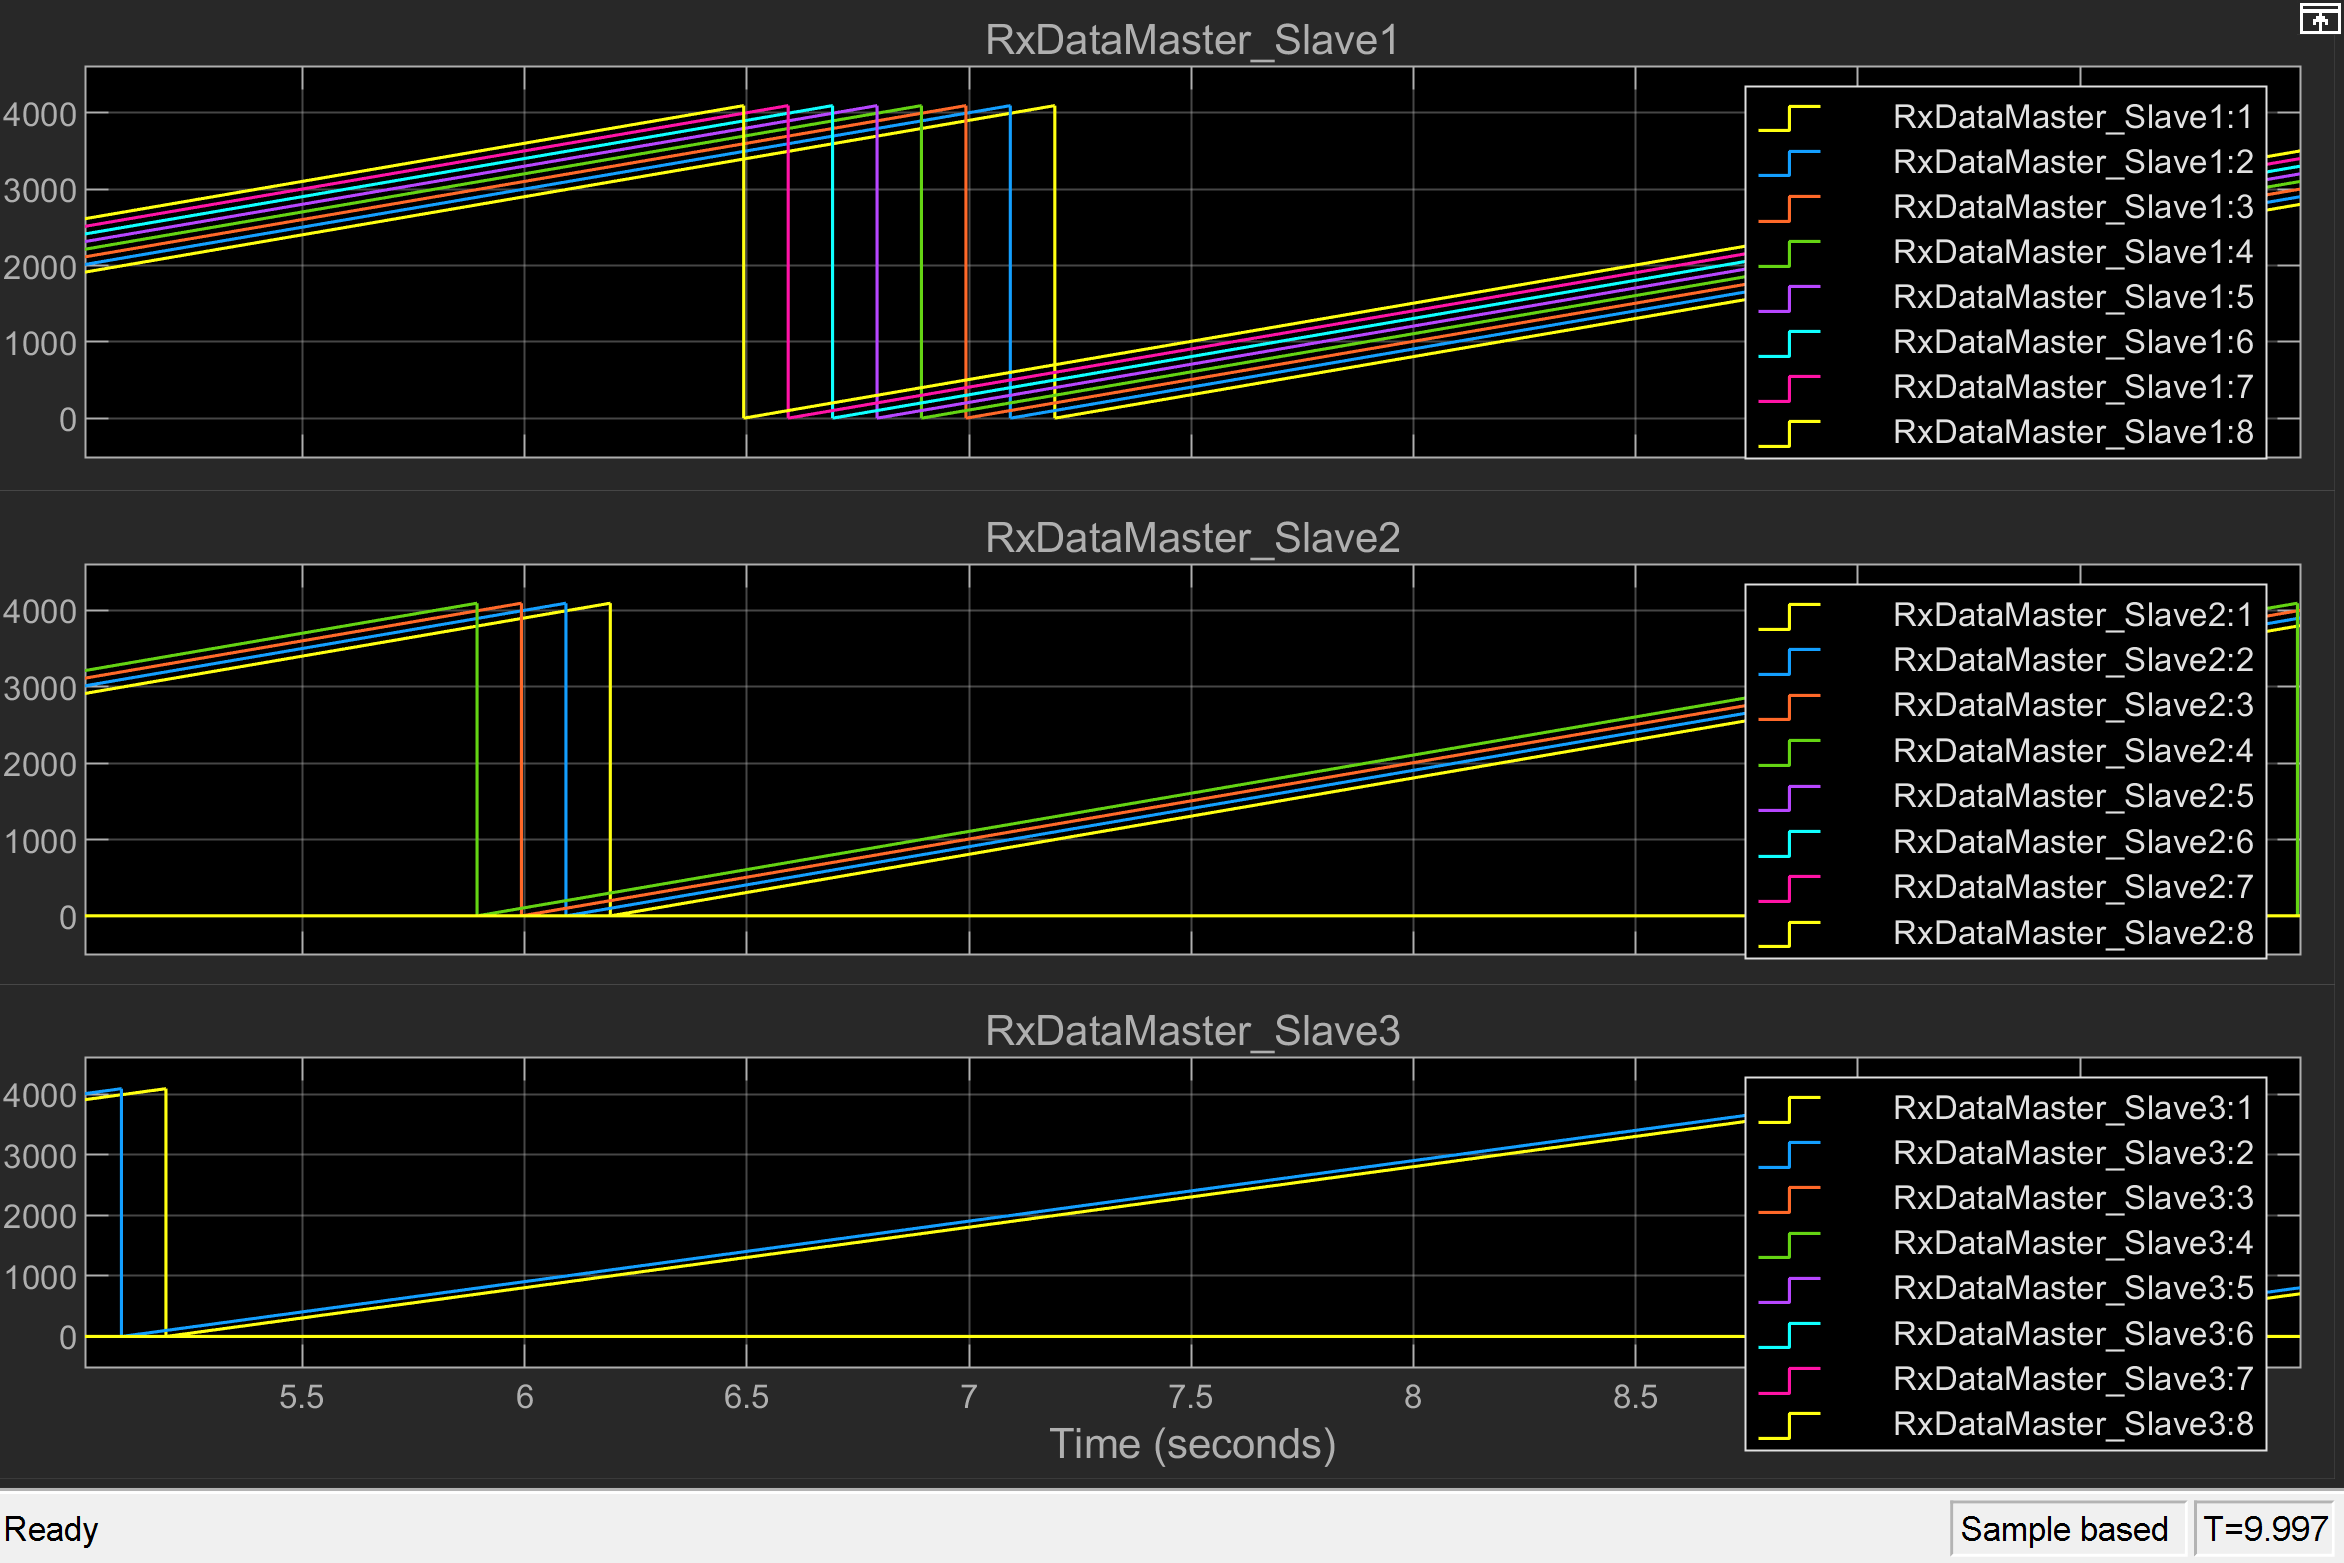

The data is based on a free-running counter that overflows after $2^{12\;} =4096$ steps due to the SPI word length being set to 12 bits. Since the model sample time is set to 1 ms, this overflow happens every 4.096 seconds.

### RxDataMaster_Slave1

The **Words per Frame** parameter is set to 8 for slave 1. Therefore, all data words (1:8) contain data.

### RxDataMaster_Slave2

Due to the **Words per Frame** on the second slave SPI is only 4 but the master requests 8 words per frame, we can only observe the data words 1:4 and the other data (5:8) is all 0.

### RxDataMaster_Slave3

Due to the **Words per Frame** on the third slave SPI is only 2 but the master requests 8 words per frame, we can only observe the data words 1:2 and the other data (3:8) is all 0.

### Received Data at Slaves

To check if the loopback is working as expected, open the Simulink scope **Data Rx Master** that is connected to the following signals:

- RxDataMaster_Slave1: The received data on the SPI Slave1 from master is displayed here. They should be equal to the SPI master Tx data.

- RxDataMaster_Slave2: The received data on the SPI Slave2 from master is displayed here. They should be equal to the SPI master Tx data.

- RxDataMaster_Slave3: The received data on the SPI Slave3 from master is displayed here. They should be equal to the SPI master Tx data.

- Valid: Since the model is running at a slower rate than the SPI frame length, we see data at every model step, therefore these signals are expected to be 1 all the time.

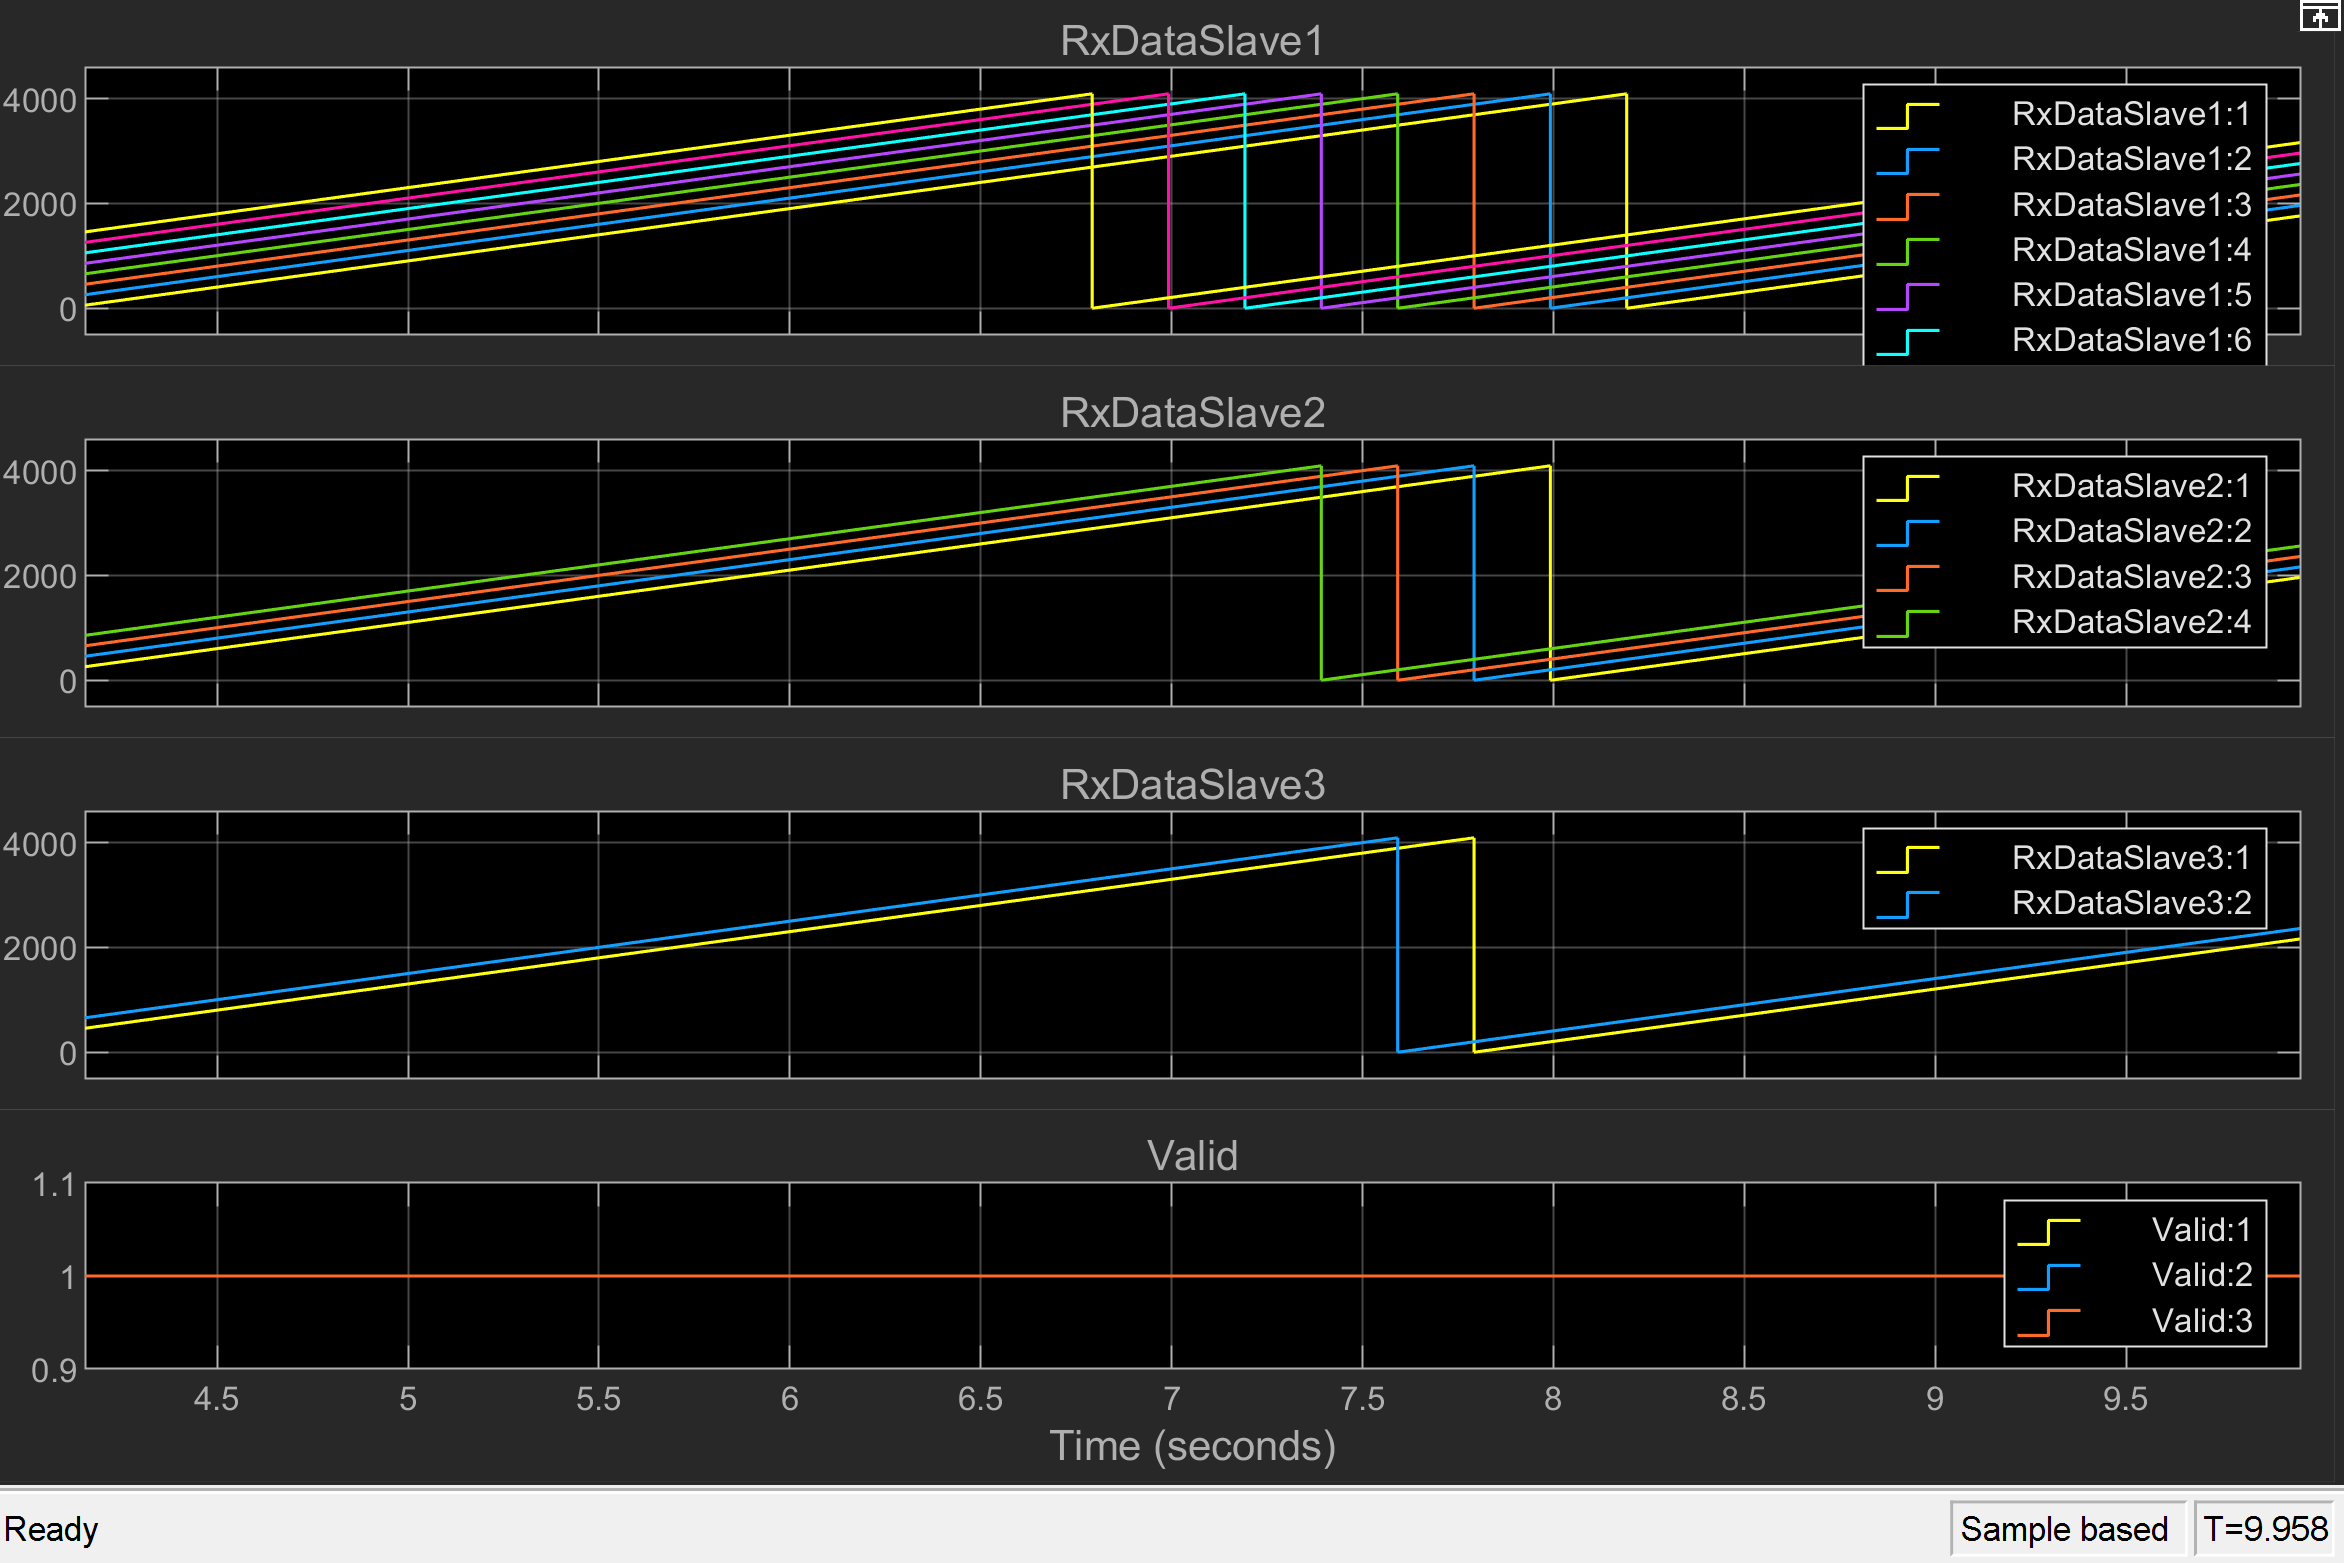

The data is based on a free-running counter that overflows after $2^{12\;} =4096$ steps due to the SPI word length being set to 12 bits. Since the model sample time is set to 1 ms, this overflow happens every 4.096 seconds.

### RxDataSlave1

The **Words per Frame** parameter is set to 8 for slave 1. Therefore, we see all data (1:8) that have been sent from the master.

### RxDataSlave2

Due to the **Words per Frame** on the second slave SPI is only 4 (but the master transfers 8 words per frame), we can only observe the data words 1:4 while the other data from the master are ignored by the SPI slave itself.

### RxDataMaster_Slave3

Due to the **Words per Frame** on the second slave SPI is only 2 (but the master transfers 8 words per frame), we can only observe the data words 1:2 while the other data from the master are ignored by the SPI slave itself.

## Additional References

The following links describe the SPI and all its parameters in details:

- [SPI v2 Driver Block](https://www.speedgoat.com/help/slrt/page/io_main/refentry_spi_masterslave_v2)

- [SPI Usage Notes](https://www.speedgoat.com/help/slrt/page/io_main/refentry_spi_usage_notes)